### M. Shees Abbas (ma11212)

# Lab 3: Integrating and Differentiating 

# Continuous-Time Signals in MATLAB

Habib University

CE-251L /EE-252L Signal and Systems

**Prepared by: Dr. Shafayat Abrar and Ms. Hira Mustafa**

**Objective: **Evaluating integrals and derivatives of signals using symbolic and numerical methods.

**In-Lab: **

**Part I: **Integrating a signal using symbolic and numerical tools. 

**Part II: **Differentiating a signal using symbolic and numerical tools. 

**Post Lab:**

**Part III: **Integrating and differentiating basic signal functions like unit-impulse and unit-step.

# **task a**

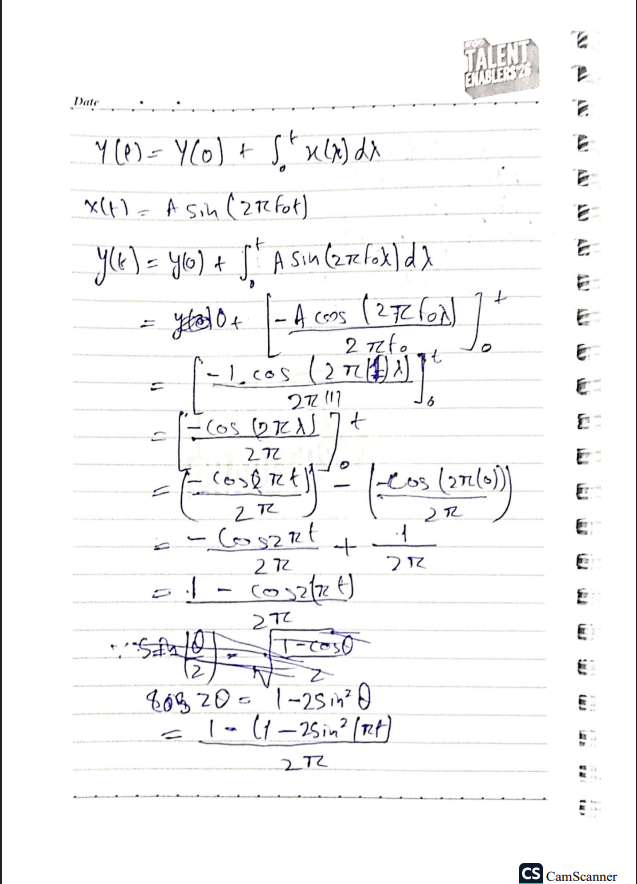

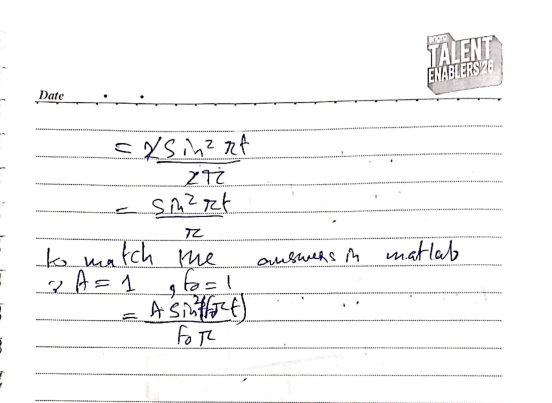

# **task B**

syms A f0 t pi
xt = A*sin(2*pi*f0*t)

$$xt = A\,\sin\left(2\,f_{0}\,\pi \,t\right)$$

yt = int(xt,'t') 

$$yt = -\frac{A\,\cos\left(2\,f_{0}\,\pi \,t\right)}{2\,f_{0}\,\pi }$$

yt = int(xt,'t',[0,t]) 

$$yt = \frac{A\,{\sin\left(f_{0}\,\pi \,t\right)}^{2}}{f_{0}\,\pi }$$

observations:

the values that i got in the task b is same as value in task but only because i knew what value i need to get while solving task a otherwise i would not have gotten to that simplified equation

# **task c**

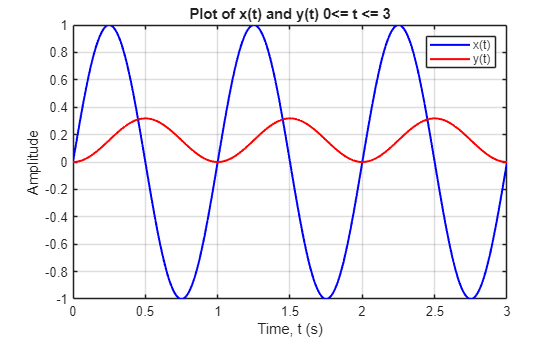

clear all;
close all;
clc
A  = 1;
f0 = 1;
t = 0:0.01:3;
x = A*sin(2*pi*f0*t);
y = (A*(sin(pi*f0*t)).^2)/(pi*f0);
figure;
plot(t, x, 'b', 'LineWidth', 1.5);
hold on;
plot(t, y, 'r', 'LineWidth', 1.5);
grid on
legend ('x(t)', 'y(t)')
xlabel('Time, t (s)');
ylabel('Amplitude');
title('Plot of x(t) and y(t) 0<= t <= 3');

# **task d**

a = [1 2 3 4 5]; 	 				
b = cumsum(a) 

b =      1     3     6    10    15


observations:

what i observed is that the each element of Array b is the sum of all the element till that index of array a

so it for each element of b it take the cumilative sum of all array a elements till that element

# **task e**

clear all;
close all;
clc
A  = 1;
f0 = 1;
dt = 0.01

dt = 0.0100

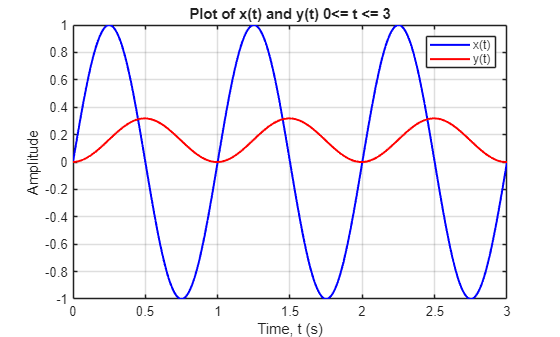

t = 0:dt:3;
x = A*sin(2*pi*f0*t);
y = dt * cumsum(x);
figure;
plot(t, x, 'b', 'LineWidth', 1.5);
hold on;
plot(t, y, 'r', 'LineWidth', 1.5);
grid on
legend ('x(t)', 'y(t)')
xlabel('Time, t (s)');
ylabel('Amplitude');
title('Plot of x(t) and y(t) 0<= t <= 3');

# **task f**

observation 

the graph created in tast b and task e is same, as we know

# **task g**

by using we numerical integration we can easily solve any equtuation no matter how complex it would be,

while solving by hand there need to be a simplified equation that we hardly would get while working real life problems

# **task h**

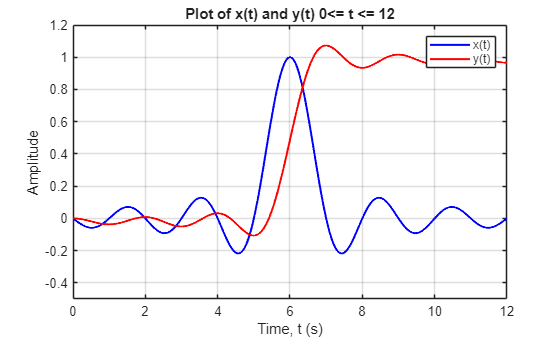

dt =0.01;
t = 0:dt:12;
x =sinc(t-6);
y = dt * cumsum(x);
figure;
plot(t, x, 'b', 'LineWidth', 1.5);
hold on;
plot(t, y, 'r', 'LineWidth', 1.5);
grid on
legend ('x(t)', 'y(t)')
xlabel('Time, t (s)');
ylabel('Amplitude');
title('Plot of x(t) and y(t) 0<= t <= 12');
axis([0 12 -0.5 1.2])

# **task i**

a = [1 2 3 4 5]

a =      1     2     3     4     5


b = diff(a)

b =      1     1     1     1


observation:

it gave me a array b and each element of b (b[i]) is the the difference of of its corresponding elements in a with the very next elemnent of it (a[i+1] - a[i])

# **task j**

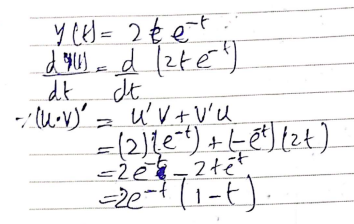

# **task k**

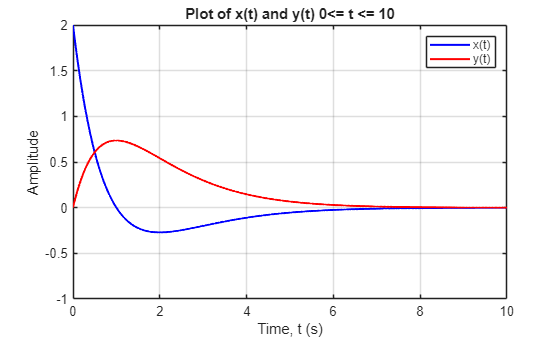

dt = 0.01;
t = 0:dt:10;
y = 2.*t.*exp(-t);
x = 2.*exp(-t).*(1-t);
figure;
plot(t, x, 'b', 'LineWidth', 1.5);
hold on;
plot(t, y, 'r', 'LineWidth', 1.5);
grid on
legend ('x(t)', 'y(t)')
xlabel('Time, t (s)');
ylabel('Amplitude');
title('Plot of x(t) and y(t) 0<= t <= 10');
axis([0 10 -1 2])

# **task l**

dt = 0.01;
t = 0:dt:10;
y = 2.*t.*exp(-t);
x = diff(y)/dt;

x =     1.9801    1.9407    1.9019    1.8636    1.8260    1.7889    1.7523    1.7163    1.6809    1.6460    1.6116    1.5777    1.5444    1.5115    1.4792    1.4474    1.4160    1.3851    1.3547    1.3248    1.2953    1.2663    1.2377    1.2096    1.1819    1.1546    1.1278    1.1014    1.0754    1.0498    1.0246    0.9998    0.9754    0.9514    0.9278    0.9045    0.8816    0.8591    0.8370    0.8152    0.7937    0.7726    0.7518    0.7314    0.7113    0.6916    0.6721    0.6530    0.6342    0.6157


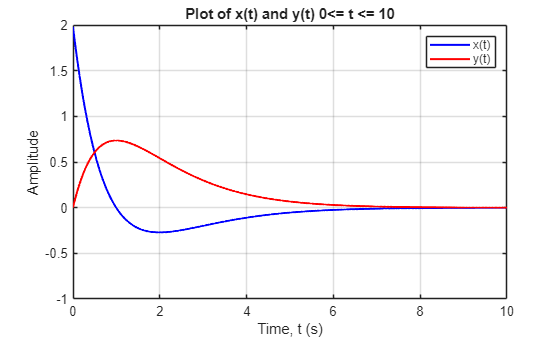

figure;
plot(t(1:end-1), x, 'b', 'LineWidth', 1.5);
hold on;
plot(t, y, 'r', 'LineWidth', 1.5);
grid on
legend ('x(t)', 'y(t)')
xlabel('Time, t (s)');
ylabel('Amplitude');
title('Plot of x(t) and y(t) 0<= t <= 10');
axis([0 10 -1 2])

# **task m**

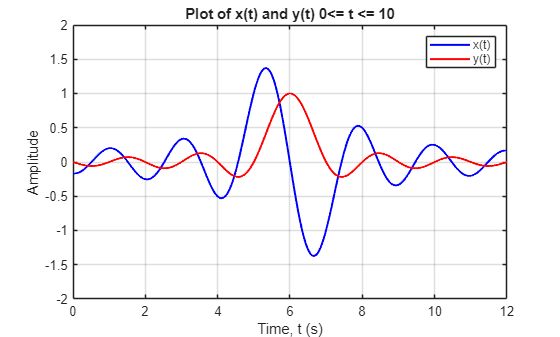

dt = 0.01;
t = 0:dt:12;
y = sinc(t-6);
x = diff(y) / dt;
figure;
plot(t(1:end-1), x, 'b', 'LineWidth', 1.5);
hold on;
plot(t, y, 'r', 'LineWidth', 1.5);
grid on
legend ('x(t)', 'y(t)')
xlabel('Time, t (s)');
ylabel('Amplitude');
title('Plot of x(t) and y(t) 0<= t <= 10');
axis([0 12 -2 2])

# **task n**

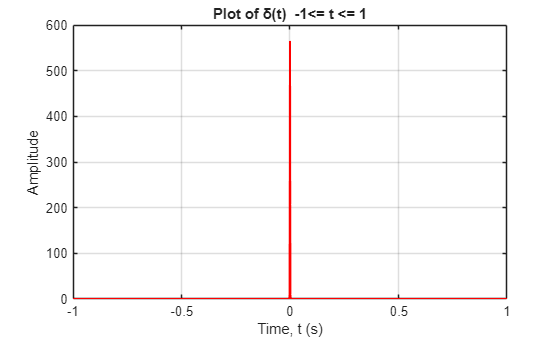

dt = 0.001;
a = 0.001;
t = -1:dt:1;
U_impulse = 1/(a*sqrt(pi))*exp((-t.^2)/a^2);
figure;
plot(t, U_impulse, 'r', 'LineWidth', 1.5);
grid on
xlabel('Time, t (s)');
ylabel('Amplitude');
title('Plot of δ(t)  -1<= t <= 1');

# **task o**

s = sum (U_impulse);
y = dt*s

y = 1.0001

# **task p**

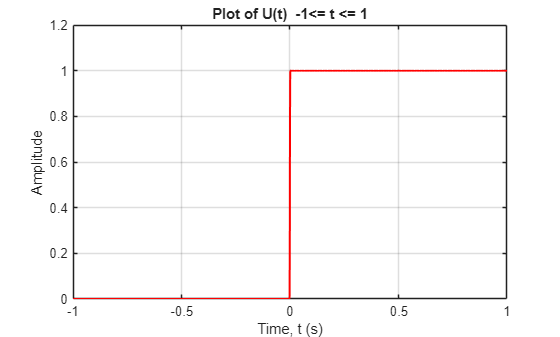

c_s = cumsum(U_impulse);
u_t = dt*c_s;
plot(t, u_t, 'r', 'LineWidth', 1.5);
grid on
xlabel('Time, t (s)');
ylabel('Amplitude');
title('Plot of U(t)  -1<= t <= 1');

# **task q**

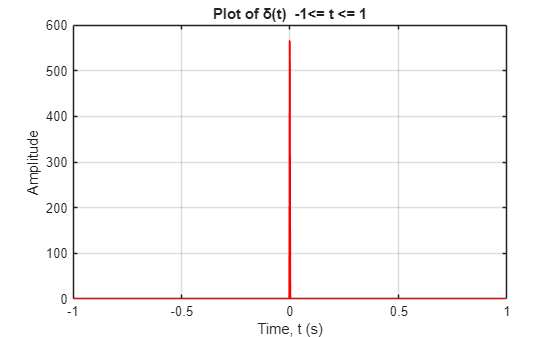

U_imp = diff(u_t)/dt;
plot(t(1:end-1), U_imp, 'r', 'LineWidth', 1.5);
grid on
xlabel('Time, t (s)');
ylabel('Amplitude');
title('Plot of δ(t)  -1<= t <= 1');